%%% LOAD IN CNN FIRST %%%
net = googlenet;
imageFolder = './data'; 
imds = imageDatastore(imageFolder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames'); 

[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.7, 'randomized');

% Preprocess Images
inputSize = net.Layers(1).InputSize;
augmenter = imageDataAugmenter('RandXReflection', true, ...
                               'RandXTranslation', [-10 10], ...
                               'RandYTranslation', [-10 10]);
augimdsTrain = augmentedImageDatastore(inputSize(1:2), imdsTrain, 'DataAugmentation', augmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2), imdsValidation);

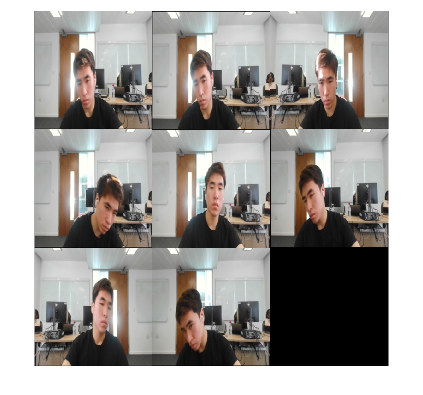

% Read a batch of augmented images
dataBatch = preview(augimdsTrain);
figure;
montage(dataBatch.input);

% Training options
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 5, ...
    'MaxEpochs', 4, ...
    'InitialLearnRate', 3e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsValidation, ...
    'ValidationFrequency', 3, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |        0.00% |       32.35% |       2.0576 |       1.6715 |          0.0003 |
|       1 |           3 |       00:00:13 |        0.00% |       32.35% |       2.5816 |       1.3523 |          0.0003 |
|       1 |           6 |       00:00:20 |       40.00% |       38.24% |       1.1746 |       1.2091 |          0.0003 |
|       1 |           9 |       00:00:28 |       40.00% |       64.71% |       1.5162 |   

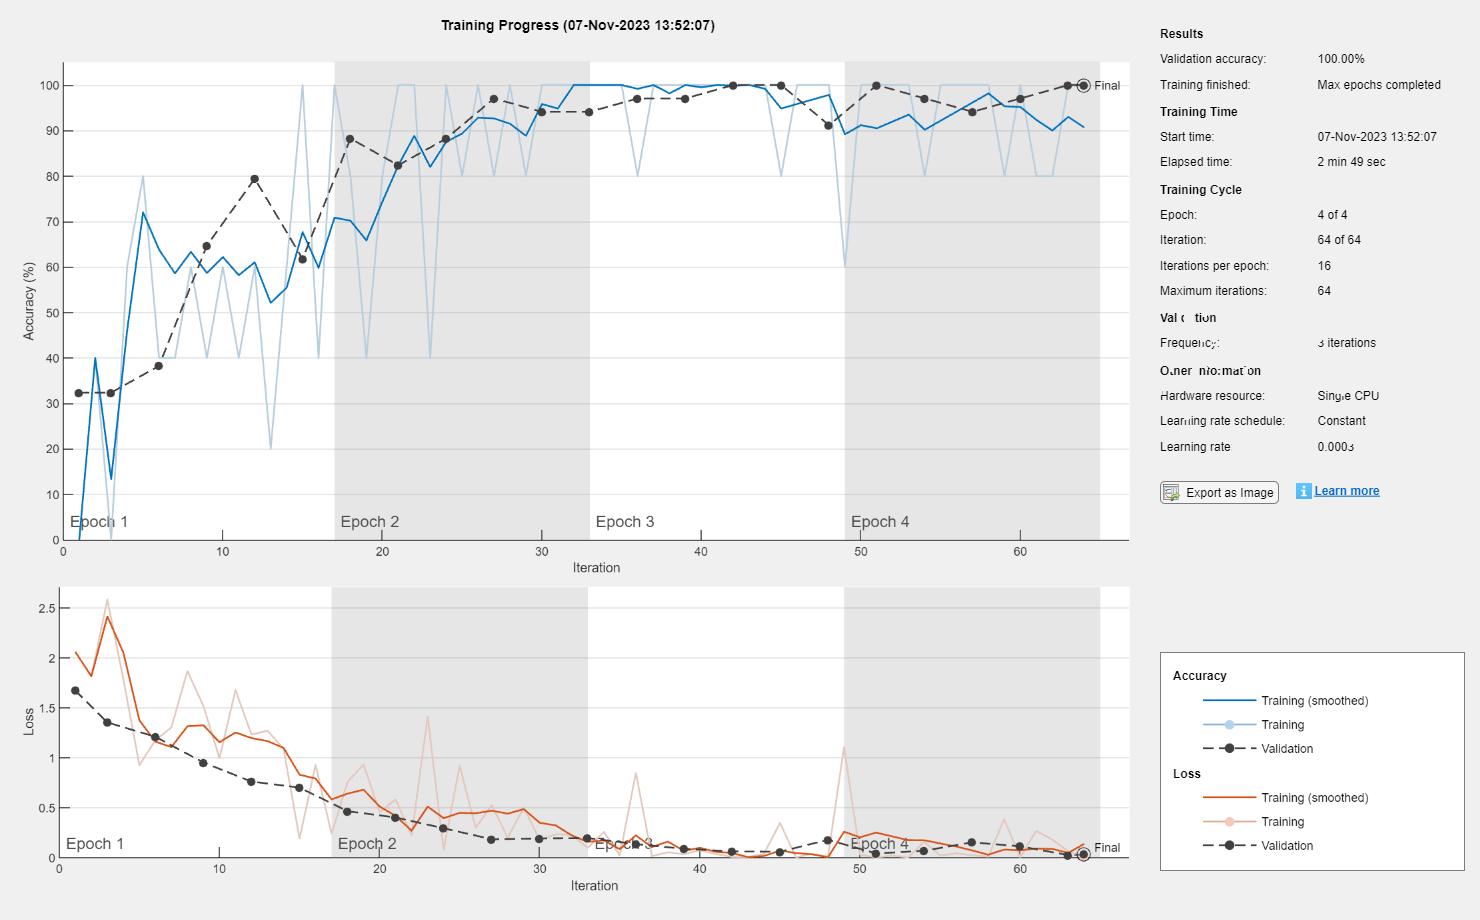

% Train model
[netTransfer, info] = trainNetwork(augimdsTrain, lgraph_1, options);

% Evaluation
YPred = classify(netTransfer, augimdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation);
fprintf('Validation accuracy: %.2f%%\n', accuracy * 100);

Validation accuracy: 100.00%


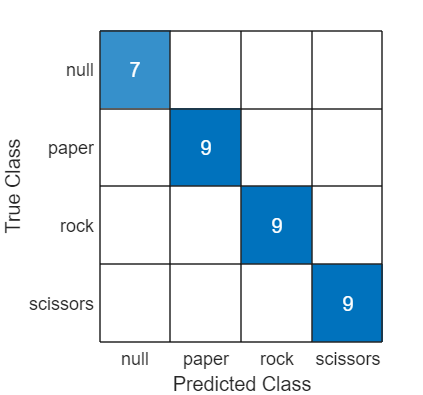


confusionchart(YValidation, YPred);

%run_network_on_webcam(netTransfer, 0.4)
%inferImage(netTransfer, "IMAGE_DIR")